# Q2(c)

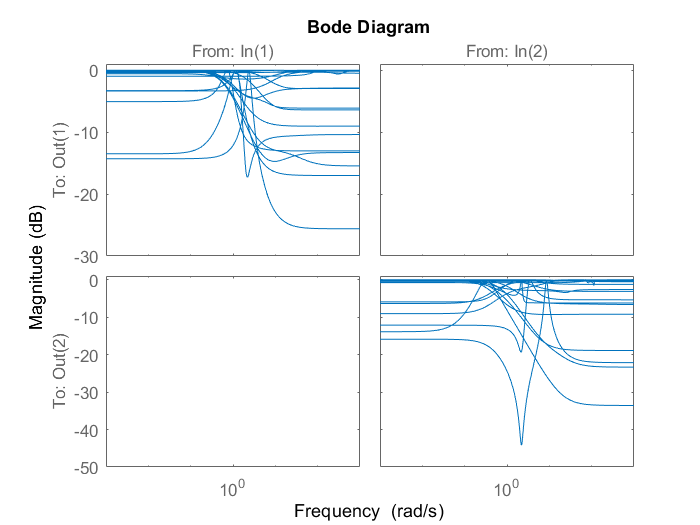

s = tf('s');
G = [-87.8 1.4;-108.2 -1.4]/(75*s+1);
K = 0.7*inv(G,'min')/s;
Wi = (s+0.2)/(0.5*s+1);
Wp = eye(2)*(0.5*s+0.05)/(s+1e-10);
del_1 = ultidyn('del1',1);
del_2 = ultidyn('del2',1);
del_full = ultidyn('delfull',[2,2]);
bodemag([del_1 0;0 del_2])

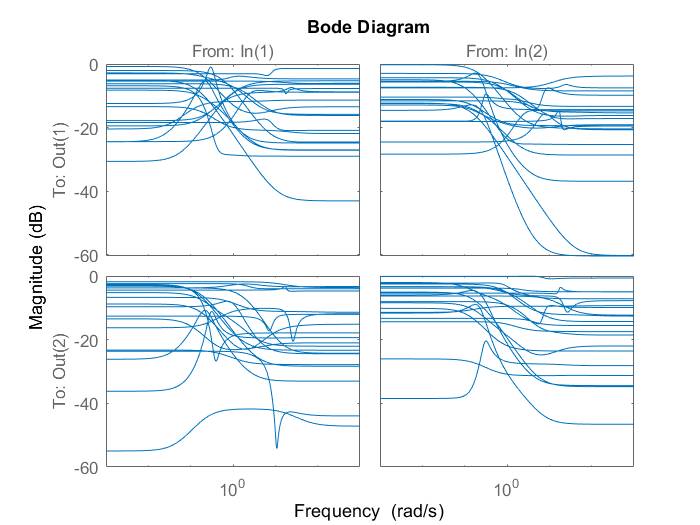

bodemag(del_full)


G_hat_diag = G*(eye(2) + Wi*[del_1 0;0 del_2])

G_hat_diag =

  Uncertain continuous-time state-space model with 2 outputs, 2 inputs, 4 states.
  The model uncertainty consists of the following blocks:
    del1: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences
    del2: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences

Type "G_hat_diag.NominalValue" to see the nominal value, "get(G_hat_diag)" to see all properties, and "G_hat_diag.Uncertainty" to interact with the uncertain elements.



G_hat_full = G*(eye(2) + Wi*del_full)

G_hat_full =

  Uncertain continuous-time state-space model with 2 outputs, 2 inputs, 4 states.
  The model uncertainty consists of the following blocks:
    delfull: Uncertain 2x2 LTI, peak gain = 1, 1 occurrences

Type "G_hat_full.NominalValue" to see the nominal value, "get(G_hat_full)" to see all properties, and "G_hat_full.Uncertainty" to interact with the uncertain elements.




S_hat_diag = eye(2) - feedback(G_hat_diag*K,eye(2));
S_hat_full = eye(2) - feedback(G_hat_full*K,eye(2));

[STABMARG,WCU] = robuststab(S_hat_diag);
mu_s = 1/STABMARG.LowerBound

mu_s = 0.5261

[PERFMARG,WCU] = robustperf(Wp*S_hat_diag);
mu_p = 1/PERFMARG.LowerBound

mu_p = 0.9670


[STABMARG,WCU] = robuststab(S_hat_full);
mu_s = 1/STABMARG.LowerBound

mu_s = 0.5261

[PERFMARG,WCU] = robustperf(Wp*S_hat_full);
mu_p = 1/PERFMARG.LowerBound

mu_p = 4.1091